# Task A: RR Robot arm

clear;
close all;
clc;

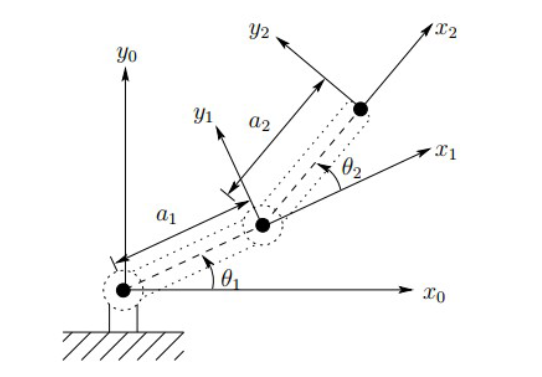

## Initial variables and parameters:

- $a_1$: 1m

- $a_2$: 0.75 m

- $\theta_1$: 10°

- $\theta_2$: 45°

- $x$: 1.4150 m

- $y$: 0.7880 m

a1 = 1;
a2 = 0.75;
theta1_init = deg2rad(10);
theta2_init = deg2rad(45);
X2_init = 1.415;
Y2_init = 0.788;

## Objective:

- We want the operator to move in a smooth manner, so that in **3.5 seconds** the tip is in the position **(x, y) = (1.4406, 0.9821)** where it will be immobilized.

- Determine the trajectories of the variables of its joints and give the graphs of their **position**, **velocity** and **acceleration** as a function of time.

X2_end = 1.4406;
Y2_end = 0.9821;

X2_traj = [X2_init, X2_end];
Y2_traj = [Y2_init, Y2_end];

t_end = 3.5;

## Forward kinematics equations:

The known forward kinematics equations are:


$$\begin{array}{l}
x=a_1 \cdot \cos \left(\theta_1 \right)+a_2 \cdot \cos \left(\theta_1 +\theta_2 \right)\\
y=a_1 \cdot \sin \left(\theta_1 \right)+a_2 \cdot \sin \left(\theta_1 +\theta_2 \right)
\end{array}$$


## Visualization of the work space:

For optimal tracetory planning first the visualization of the work space and the planned position path should be performed.

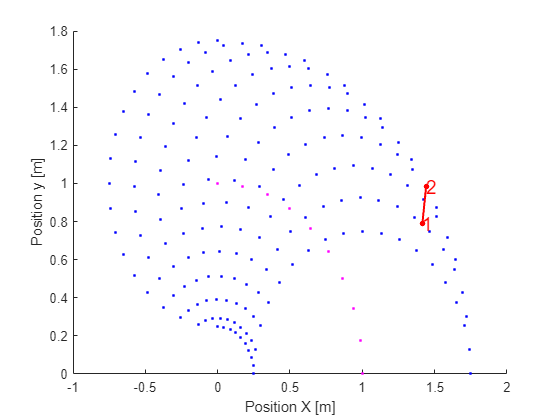

% All possible angle for theta1 and theta2 in the selected frame are 0 to
% 90°
theta1 = 0:10:90;
theta2 = 0:10:180;

% Convert deg in rad
theta1 = deg2rad(theta1);
theta2 = deg2rad(theta2);

% Generate grid of angle values
[THETA1,THETA2] = meshgrid(theta1,theta2);

% Calculate all possible X and Y positions
X1 = a1.*cos(THETA1);
Y1 = a1.*sin(THETA1);
X2 = X1 + a2.*cos(THETA1 + THETA2);
Y2 = Y1 + a2.*sin(THETA1 + THETA2);

% Visualization
figure
hold on
plot(X1,Y1,'m.')
plot(X2,Y2,'b.')
plot(X2_traj,Y2_traj,'r.','LineStyle','-','MarkerSize',12,'LineWidth',1.5)
text(X2_traj(1),Y2_traj(1),'1','Color','r','FontSize',14)
text(X2_traj(2),Y2_traj(2),'2','Color','r','FontSize',14)
hold off

xlabel('Position X [m]')
ylabel('Position y [m]')

## Inverse kinematics equations:

With the geometric method the inverse kinematics equations can be formulated to calculate the joint angles:


$$\theta_2 =\arccos \left(\frac{x^2 +y^2 -a_1^2 -a_2^2 }{2a_1 a_2 }\right)$$



$$\theta_1 =\arctan \left(\frac{y}{x}\right)-\arctan \left(\frac{a_2 \sin \left(\theta_2 \right)}{a_1 +a_2 \cos \left(\theta_2 \right)}\right)$$


% Calculate joint angles
theta2_start = acos((X2_init.^2 + Y2_init.^2 - a1^2 - a2^2)/(2*a1*a2));
theta1_start = atan(a1*sin(theta2_start)./a1*cos(theta2_start)) - atan((a2.*sin(theta2_start))./(a1 + a2.*cos(theta2_start)));
theta2_end = acos((X2_end.^2 + Y2_end.^2 - a1^2 - a2^2)/(2*a1*a2));
theta1_end = atan(a1*sin(theta2_end)./a1*cos(theta2_end)) - atan((a2.*sin(theta2_end))./(a1 + a2.*cos(theta2_end)));

% Convert rad to deg
theta2_start = rad2deg(theta2_start);
theta1_start = rad2deg(theta1_start);
theta2_end = rad2deg(theta2_end);
theta1_end = rad2deg(theta1_end);

% Time array
t = 0:0.01:3.5;

## Position trajectory

To get a smooth position trajectory cubic polynomials are selected. Thus the angle position is described by:


$$\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3$$



$$\dot{\;\theta } \left(t\right)=a_1 +2a_2 t+3a_3 t^2$$



$$\ddot{\;\theta } \left(t\right)=2a_2 +6_3 t$$


For a smooth and continous trajectory it is recommended that in the start and end position the velocity is equal to zero. Thus to equation for angle position equals to (see function "getCubicTraj"):


$$\theta \;\left(t\right)=\theta {\;}_{\int } +\frac{3}{t_{\mathrm{end}}^2 }\left(\theta_{\mathrm{end}} -\theta_{\mathrm{init}} \right)t^2 -\frac{2}{t_{\mathrm{end}}^3 }\left(\theta_{\mathrm{end}} -\theta_{\mathrm{init}} \right)t^3$$


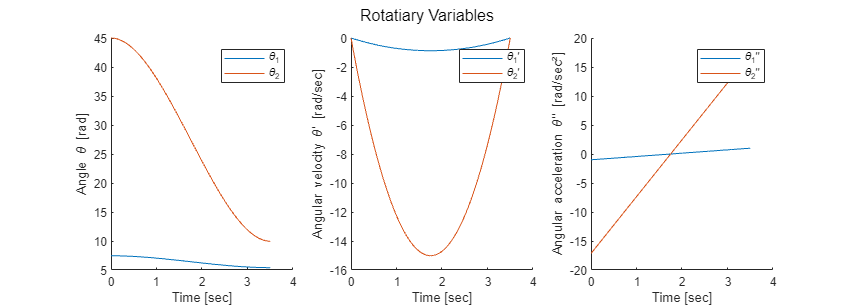

% Calculate positions, velocities & accelerations
[theta2,theta2_dot,theta2_ddot] = getCubicTraj(t,t_end,theta2_start,theta2_end);
[theta1,theta1_dot,theta1_ddot] = getCubicTraj(t,t_end,theta1_start,theta1_end);

% Plot angle, angular velocity and acceleration
figure('Position',[10 10 1400 500])
subplot(1,3,1)
hold on
plot(t,theta1,'DisplayName','\theta_1')
plot(t,theta2,'DisplayName','\theta_2')
hold off
legend
xlabel('Time [sec]')
ylabel('Angle \theta [rad]')

subplot(1,3,2)
hold on
plot(t,theta1_dot,'DisplayName','\theta_1\prime')
plot(t,theta2_dot,'DisplayName','\theta_2\prime')
hold off

legend
xlabel('Time [sec]')
ylabel('Angular velocity \theta\prime [rad/sec]')

subplot(1,3,3)
hold on
plot(t,theta1_ddot,'DisplayName','\theta_1\prime\prime')
plot(t,theta2_ddot,'DisplayName','\theta_2\prime\prime')
hold off
legend
xlabel('Time [sec]')
ylabel('Angular acceleration \theta\prime\prime [rad/sec²]')
sgtitle('Rotatiary Variables')

## Sources:

- Dr.-Ing. John Nassour, "Inverse Kinematics - Serial link manipulators". Artificial Intelligence & Neuro Cognitive Systems FakultätfürInformatik. Technische Universität Chemnitz. 22.11.2016

- Dr.-Ing. John Nassour, "Trajectory Generation". Artificial Intelligence & Neuro Cognitive Systems FakultätfürInformatik. Technische Universität Chemnitz. 11.01.2017